Name: Saikrishna Saketh Y

Student Number: 723400

**A quick report**

- BER is observed to be 0 for 50% of the Simulation

- Selection Parameters of Fo, Fb, and Fs are chosen according to the underlying instructions, I chose Fo, which is strictly less than 15Khz

- Fb is chosen in such a manner that cycles/bit is an integer

- Roll off factor is Beta, which is chosen as 1, it provides most optimal bandwidth, 

% Differential binary phase-shift keying + pulse shaping + FM transmitter
% and RTL-SDR 
%
% By R.W.

clear all, close all

% addpath ../funcs
% ==================================================================
%Script to set parameters
%rw_fmrx_init

% File to dump the output signal
fnam = 'dbpsk_signal.wav';

% Parameters to choose:
 Fb = 3e3;
% Frequency of the information bits to send.
 Fo = 12e3;
% % Sampling rate of the FM modulator's input signal. 
% Note that the FM bandwidth is 15 KHz
 Fs = 120e3;
% Over-sampling factor is therefore Fs/Fo
%
% Implement DBPSK encoding rw_dbpsk_encode 
% Implement pulse shaping filter rw_pulse_shaping 
% Implement FM demodulator rw_fmrx
% Implement decimation to audio sampling rate rw_dec_audio
% Implment matched filter for the transmitted pulse rw_matched_pulse
% Implement matched filter for the up-sampled preamble
% rw_matched_preamble_up
% Implement DBPSK decoding rw_dbpsk_decode
% Except rw_fmrx and rw_dbpsk_encode, these are on-line anonymous functions

% Preamble: Maximum length sequence
pnseq=comm.PNSequence('Polynomial',[5 2 0],'SamplesPerFrame',31,...
    'InitialConditions',[0 0 0 0 1]);
pn31 = sign(pnseq()' -0.5);
preamble = pn31;

% Typically the overhead from control signaling in wireless sytems is 10-20%
% Here preamble is the only control signal (no channel estimation, power
% control command, system information...) so the overhead can be smaller.
% It's arbitrary in this exercise anyway.
% #Information bits/message
Nbit = 300-length(preamble);
% Sets the seed for the random generator so that the message is always the
% same
rng(2308975234);
% Message consists of +- ones
msg = sign(randn(1,Nbit));

% Differential modulation for the message. First bit of the encoded
% message=1
msg(1)=1; 
dbpsk_msg = rw_dbpsk_encode(msg);

% A slot consists of the header and the payload
slot = [preamble,dbpsk_msg]; 
% A frame consists of Nslot slots
Nslot = 8;
frame = kron(ones(1,Nslot), slot);

% Make msg a column vector for the compatibility of dimensions
msg = msg(:);

% front-end sampling rate, 
FESR = 240e3;
% Read two slots at a time. This way there is at least one
% complete slot in one vector read by the dongle
Nsample = 2*FESR/Fb*length(slot);
% #Output vectors to read from the dongle
Nloop = 100;

% ===========================================================================

## Part 1: Make the signal to transmit

Make a wav file that is then used as input to FM transmitter DBPSK odulation and shaping. Sine wave signals bit 1 Information signal for FM modulation at sampling frequency Fs

dbpsk_signal = rw_pulse_shaping(frame,Fs/Fo);

% It's necessary to normalize the range [-1,1] for audiowrite
dbpsk_signal = dbpsk_signal/max(abs(dbpsk_signal));

## Write the frame into audio file

This file is then transmitted with the FM transmitter Dongle has 8-bit analog-to-digital converter, so use the same number here

audiowrite(fnam,kron(ones(1,50),dbpsk_signal),Fs,'BitsPerSample',8,...
	'Title','DBPSK signal','Artist','RW','Comment',date)
audioinfo(fnam)

ans = struct with fields:
             Filename: 'F:\Aalto\Course_Work_&_Modules\Period I-II 2018\Signal_Processing_for_Comm\Code\E5410-master\matlab\task_8\dbpsk_signal.wav'
    CompressionMethod: 'Uncompressed'
          NumChannels: 1
           SampleRate: 120000
         TotalSamples: 1200000
             Duration: 10
                Title: 'DBPSK signal'
              Comment: '06-Dec-2018'
               Artist: 'RW'
        BitsPerSample: 8



% The way to run audio in Ubuntu with Alsa 
%system('speaker-test -r sampling-rate -l 0 -t wav -W . -w fm_data.wav')
% 
% In /bin/bash
% while :; do afplay -r sampling-rate fm_data.wav; done
%
% Quicktime in Mac, Mediaplayer in Windows
% In Windows we play
%powershell -c (New-Object Media.SoundPlayer "c:\PathTo\YourSound.wav").PlaySync();
%
% Or upload to a phone and transmit
%
% Put your system to transmit until you move on to the receiver part


% ============================================================================

## Part 2: Receive

Radio parameters. Find an empty channel without any FM station

expFreq = 89.5e6;

hSDRrRx = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency',     expFreq, ...
    'EnableTunerAGC',      true, ...
    'SampleRate',          FESR, ...
    'SamplesPerFrame',     Nsample, ...
    'FrequencyCorrection', 40, ...
    'OutputDataType',      'double');

hSpectrumAnalyzer = dsp.SpectrumAnalyzer(...
    'Name',             'Actual Frequency Offset',...
    'Title',            'Actual Frequency Offset', ...
    'SpectrumType',     'Power density',...
    'FrequencySpan',    'Full', ...
    'SampleRate',       FESR, ...
    'YLimits',          [-60,10],...
    'SpectralAverages', 10, ...
    'FrequencySpan',    'Start and stop frequencies', ...
    'StartFrequency',   -50e3, ...
    'StopFrequency',    50e3,...
    'Position',         figposition([50 30 30 40]));

## Rx loop

if isempty(sdrinfo(hSDRrRx.RadioAddress))
    warning(message('SDR:sysobjdemos:MainLoop'))
    return
end

% Time elapsed
fprintf('Loop time: %f s\n',Nsample*Nloop/FESR)

Loop time: 20.000000 s


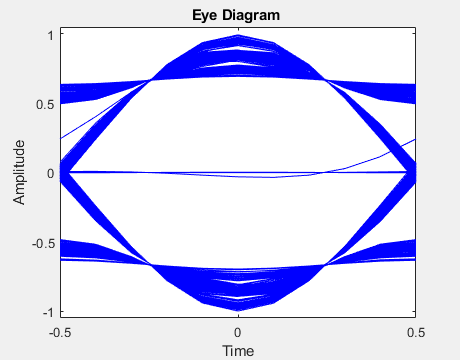

% Allocate memory for signal storage
%rxSigStore = zeros(1,Nsample*Nloop);
ber_vec = ones(1,Nloop);
fb = figure('Name', 'BER');
hb = animatedline('Marker','o');
axis([0 Nloop 0 1]);
% 
heye = eyediagram(dbpsk_signal,Fs/Fo);    

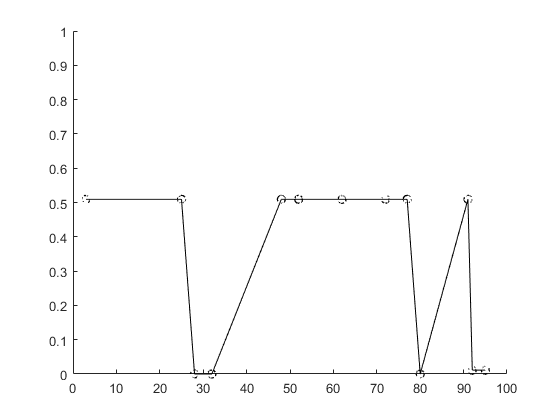

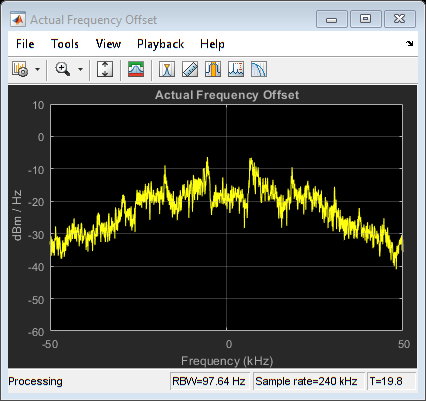

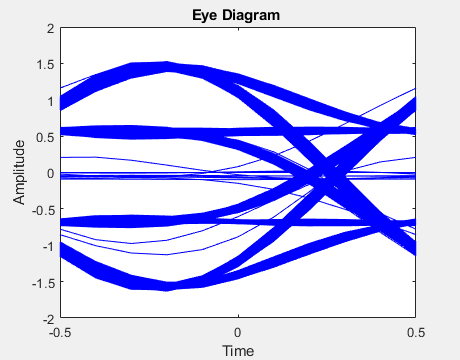

tstart = tic;
for ii = 1:Nloop
    [rxSig, ~] = step(hSDRrRx);
    rxSig = rxSig - mean(rxSig);  % Remove DC component
        
    % Display received frequency spectrum
    hSpectrumAnalyzer(rxSig);
    
    %rxSigStore((iFrame-1)*SPF+[1:SPF]) = rxSig;
    % FM demodulator using discriminator
    rd = rw_fmrx(rxSig,FESR);
 
    % Decimate to audio sampling rate first
    rd_audio = rw_dec_audio(rd,FESR/Fs);
 
    % Matched filtering with the pulse shaping filter
    after_mf = rw_matched_pulse(rd_audio,Fs/Fo);    
    % Option to vheck that the Tx-Rx chain works without over-the air transmission
    % Comment out when it works
    %after_mf = rw_matched_pulse(dbpsk_signal(:));
    % Plot to the same eye diagram using figure handle heye
    eyediagram(after_mf,Fs/Fo,1,0,'b-',heye);
    
    % Find the preamble using the UP-SAMPLED preamble sequence
    % Phase can be flipped so use abs()
    ups = Fs/Fo;
    after_premf = rw_matched_preamble_up(after_mf,ups,preamble);
    [~, idx] = max(abs(after_premf));
    
    % If the index is too large so that the slot cannot start here,
    % don't attempt to decode and go read a new sample vector
    if idx+Nbit*Fs/Fo > 2*Nbit*Fs/Fo
        continue
    end

    % Index OK, down-sample and decode
    soft_bits = after_mf(idx+[Fs/Fo:Fs/Fo:Nbit*Fs/Fo]);  
    msgd = rw_dbpsk_decode(soft_bits);

    % Bit-error rate
   % ber_vec(ii) = sum((msg.*msgd) <0)/Nbit;
    ber_vec(ii) = sum(msg~=msgd')/Nbit;
    %fprintf('Bit error rate %f at round %d\n', ber_vec(ii), ii)
    % Plot BER point by point. Comment out if too slow
    addpoints(hb, ii, ber_vec(ii)), drawnow limitrate
end

fprintf('Elapsed time %f s\n', toc(tstart))

Elapsed time 97.824618 s


    
% Check the bit-error rates
%stem(ber_vec)

## Release all System objects

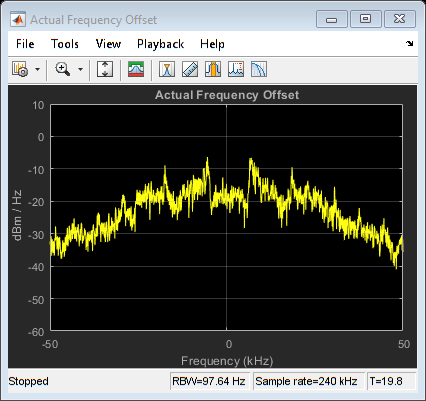

release(hSDRrRx); 
release(hSpectrumAnalyzer)

clear hSDRrRx


function dbpsk_msg = rw_dbpsk_encode(msg)
    dbpsk_msg = zeros(1,length(msg));
    dbpsk_msg(1) = 1;
%     msg1 = msg/2+0.5;
    for i=2:length(msg)
        % dbpsk_msg(i) = ~xor(dbpsk_msg(i-1),msg1(i));
%          dbpsk_msg(i) = real(dbpsk_msg(i-1)*exp(1i*pi*msg1(i)));
        dbpsk_msg(i) =  dbpsk_msg(i-1)*msg(i);
    end
end

function dbpsk_signal = rw_pulse_shaping(frame,upsampling)
    %raised_cosine = rcosdesign(0.2,length(frame),upsampling);
   raised_cosine = rcosdesign(1,16,upsampling);
   % dbpsk_signal = filter(raised_cosine,1,frame);
   dbpsk_signal = filter(raised_cosine, 1,upsample(frame, upsampling));
end

function rd = rw_fmrx(rxSig,FESR)
 filterdelay = filter([0 1],1,rxSig);
 rd = angle(filterdelay .* conj(rxSig));
 FLOW = fir1(50,15e3/(FESR/2));
 memo = zeros(1, length(FLOW)-1);
 [rd,~]=filter(FLOW,1,rd,memo);
end

function rd_audio = rw_dec_audio(rd,factor)
    rd_audio = rd(1:factor:end);
end

function after_mf = rw_matched_pulse(rd_audio,upsampling)
     raised_cosine = rcosdesign(1,16,upsampling);
     after_mf = filter(raised_cosine,1,rd_audio);
end

function after_premf = rw_matched_preamble_up(after_mf,upsampling,preamble)
%     raised_cosine = rcosdesign(1,16,upsampling);
%     preamble = upsample(preamble,upsampling);
%     filtered_preamble = filter(raised_cosine, 1, preamble);
%     after_premf = filter(fliplr(filtered_preamble),1,after_mf);
    up_pre= upsample(preamble,upsampling);%since everything is upsampled
    after_premf = filter(fliplr(up_pre),1,after_mf);
end

function msgd = rw_dbpsk_decode(soft_bits)
    msgd = zeros(1,length(soft_bits));
    msgd(1) = 1;
    for i = 2:length(soft_bits)
        msgd(i) = (conj(soft_bits(i-1))*soft_bits(i))>0;
    end
    msgd = sign(msgd-.5);
    msgd = [1 msgd(1:end-1)];
end